%% Problem 1
clear all
close all
clc 
syms s t
R = 12;
L = .15;
C = 100*(10^-6);
Zr = R;
Zl = s*L;
Zc = 1/(s*C);
Zsys = Zr+Zl+Zc;
vx = dirac(t);
Vs = laplace(vx); 
Isys = Vs/Zsys;
HRman = Zr*Isys

$$HRman = \frac{12}{\frac{3\,s}{20}+\frac{10000}{s}+12}$$

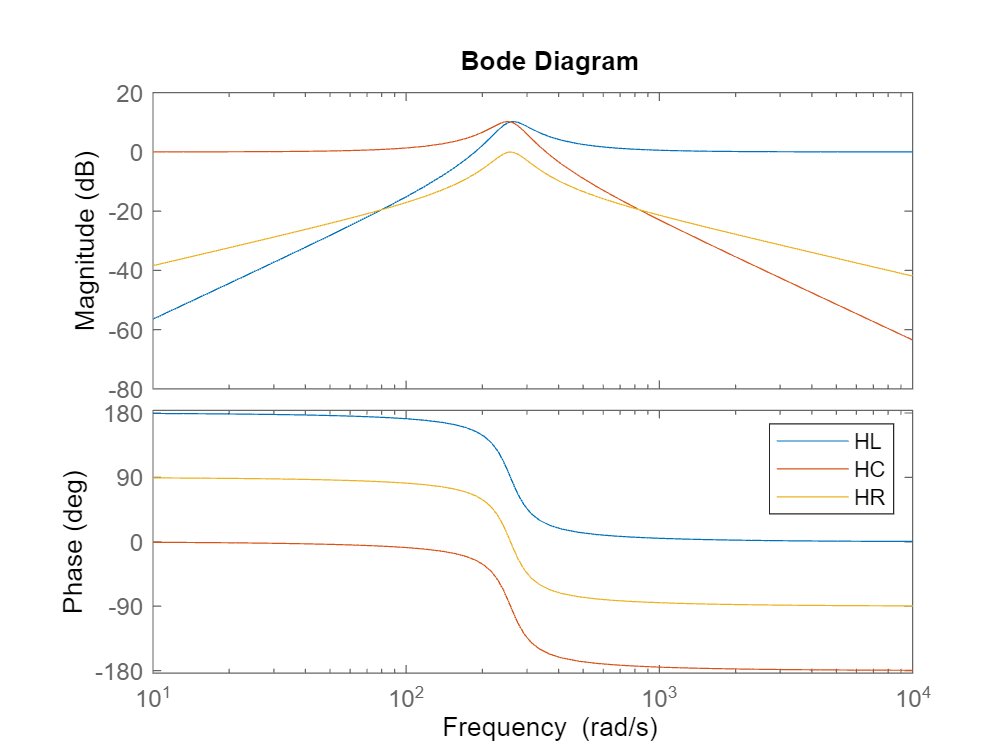



HL = tf([1.5*(10^-5) 0 0],[1.5*(10^-5) .0012 1]);
HC = tf([1],[1.5*(10^-5) .0012 1]);
HR = tf([.0012 0],[1.5*(10^-5) .0012 1]);
bode(HL)
hold on
bode(HC)
hold on
bode(HR)
hold on
legend('HL','HC','HR')
hold off

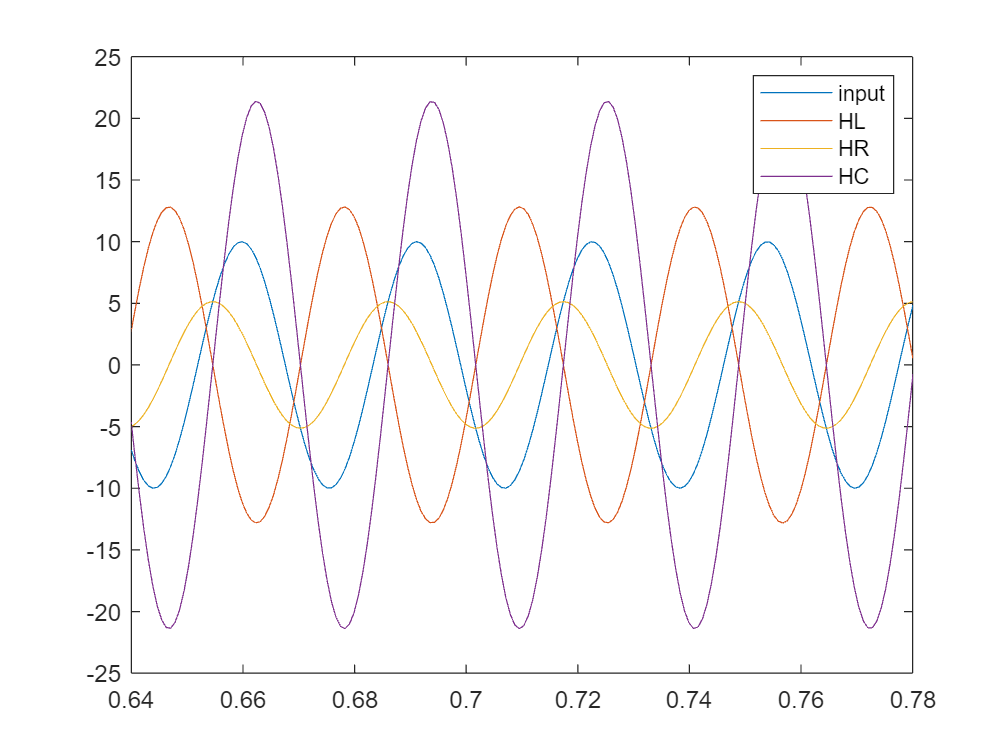


t1 = linspace(0,.8,1000);
xt1 = 10*cos(200*t1);
plot(t1,xt1)
hold on
y = lsim(HL,xt1,t1);
plot(t1,y);
hold on
y1 = lsim(HR,xt1,t1);
plot(t1,y1);
hold on
y2 = lsim(HC,xt1,t1);
plot(t1,y2);
xlim([.64,.78]);
hold on
ylim([-25,25]);
hold on
legend('input','HL','HR','HC')
hold off

%% Problem 2

syms s t
xt = heaviside(t)-heaviside(t-1);
ht = 2*heaviside(t)-2*t*heaviside(t)+2*(t-1)*heaviside(t-1)

$$ht = 2\,\mathrm{heaviside}\left(t\right)-2\,t\,\mathrm{heaviside}\left(t\right)+\mathrm{heaviside}\left(t-1\right)\,\left(2\,t-2\right)$$

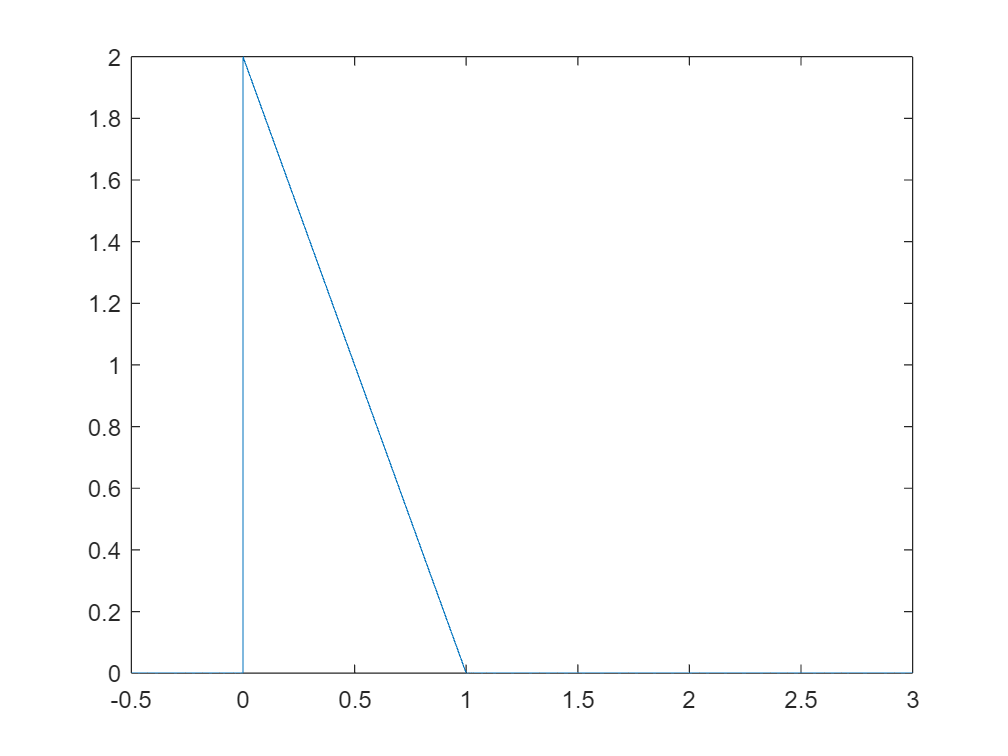

% equivalent ht => h(t) = 2(u(t)-tu(t)+(t-1)u(t-1)) %% My answer
fplot(ht)
xlim([-.5,3])
ylim([0,2])
hold off

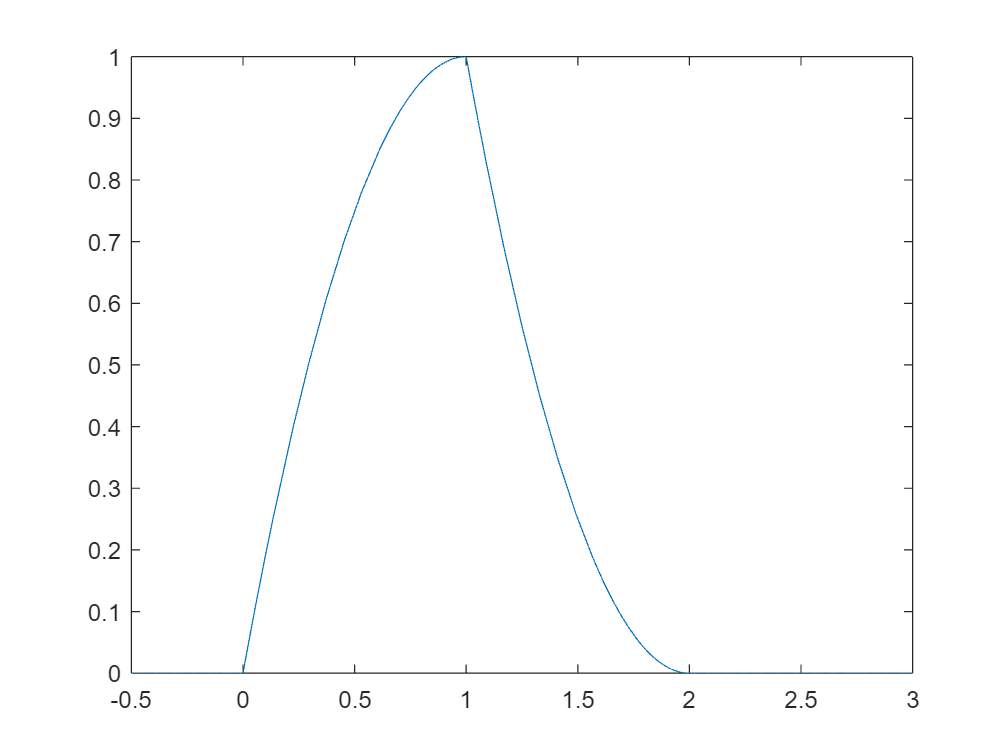

yt = heaviside(t)*ilaplace(laplace(xt)*laplace(ht));
fplot(yt)
xlim([-.5,3])
ylim([0,1])